%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and 
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package. 
% 
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
phi = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,phi(1),phi(2)-phi(1),phi(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

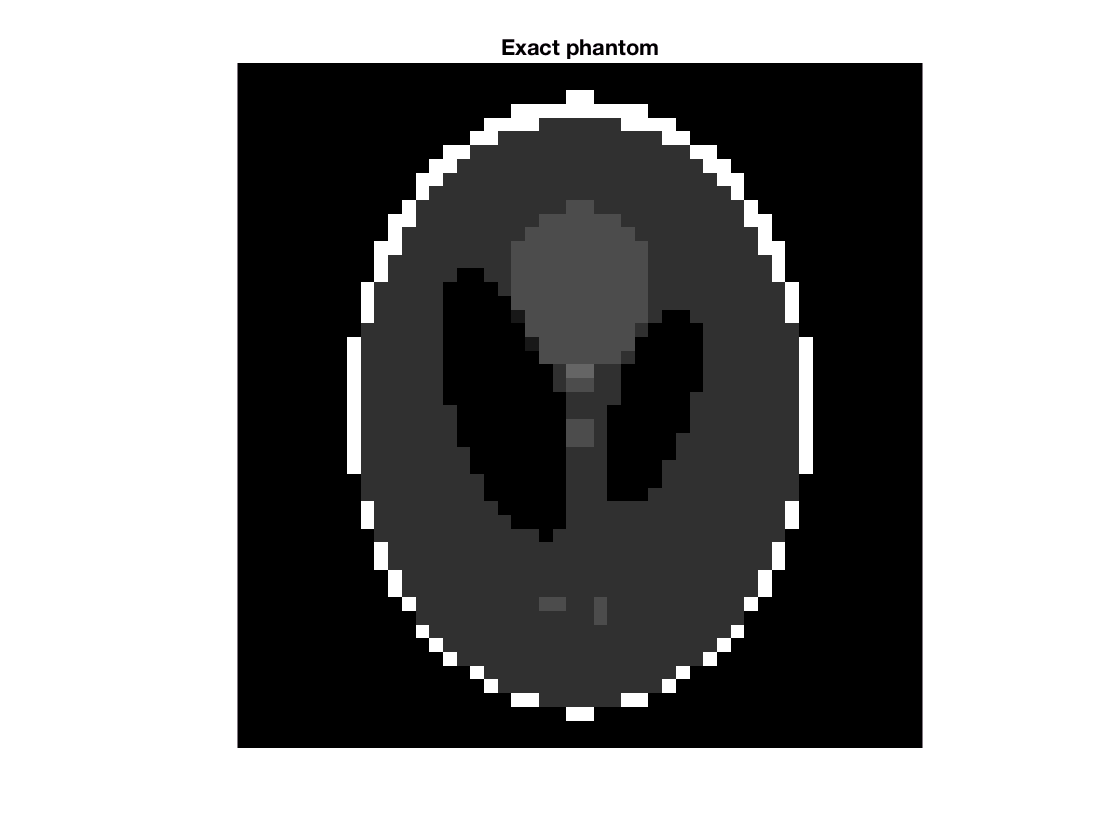


% Create the test problem.
[A,b,x] = paralleltomo(N,phi,p);

% Show the exact solution.
figure(1), clf
subplot()
% subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('Exact phantom')

fprintf(1, 'sparsity: %d', sum(x == 0))

sparsity: 1482

fprintf(1,'\n\n');


x0 = zeros(N ^ 2, 1);
plotter = Plotter(x, N, c, true);

## Necessary calculation for RSK

tic
cov_A = cov(A); % expensive
eig_cov_A = eig(cov_A); % expensive too!
min_eig = min(eig_cov_A(eig_cov_A > 0));
ita = @(t, theta) (1 + t * min_eig) ^ (-theta);
toc  % approx 4 min

## Iteration settings

k = 3;           % Number of iterations.
theta = 1;
run_robust = @(type, theta) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true,'ita', ita, 'theta', theta, 'robust', true));
run_general = @(type, theta) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true,'ita', ita, 'theta', theta));
run_special = @(type) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true));

## Perform the Kaczmarz iterations.

type = 'kaczmarz';
[Xrand, info] = run_special(type);
plotter.plot(Xrand, type);

## Perform the randomized Kaczmarz iterations.

type = 'randkaczmarz';
[Xrand, info] = run_special(type);
plotter.plot(Xrand, type);

## SK

type = 'SK';
[Xrand, info] = run_special(type);
plotter.plot(Xrand, type);

## The special RSK in [26]

type = 'RSK';
[Xrand, info] = run_special(type);
plotter.plot(Xrand, type)

## Generalized RSK

type = 'RSK';
[Xrand, info] = run_general(type,1);
plotter.plot(Xrand, type)

## Generalized RSK with theta = 0.5 

type = 'RSK';
[Xrand, info] = run_general(type,1);
plotter.plot(Xrand, type)